# Inversione Cinematica Con Algoritmo Di Newton E Del Gradiente

La prima fase consiste nella definizione del modello cinematico del manipolatore. Si utilizzano variabili simboliche per rappresentare le lunghezze dei bracci e le variabili di giunto, al fine di ottenere espressioni generali e analitiche.

clc; clear; close all;
% Variabili Di Giunto
syms q1 q2 real;

% Lunghezza Bracci
syms l1 l2 real;
% Posizione Base Giunto
x0 = 0;
y0 = 0;

% Calcolo Coordinate Fine Primo Braccio (x1, y1)
x1 = l1 * cos(q1);
y1 = l1 * sin(q1);

% Calcolo Coordinate End Effector (x2, y2) Rispetto Al Sistema Di Riferimento Base
x = x1 + l2 * cos(q1 + q2);
y = y1 + l2 * sin(q1 + q2);

% Definizione Vettore Colonna fr_q = [x; y]
fr_q = [x; y];
fr_q = simplify(fr_q);

% Definizione Vettore Variabili Di Giunto
q = [q1; q2];

fprintf('Posizione EE Rispetto Al Riferimento Base [Vettore fr(q)]');

Posizione EE Rispetto Al Riferimento Base [Vettore fr(q)]

disp(fr_q);

$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

Per sviluppare gli algoritmi di cinematica inversa, è fondamentale calcolare la matrice Jacobiana, che lega le velocità nello spazio dei giunti alle velocità nello spazio operativo.

% Calcolo Jacobiano Analitico
J_q = jacobian(fr_q, q);
J_q = simplify(J_q);
fprintf('\nJacobiano Analitico J(q):\n');


Jacobiano Analitico J(q):


disp(J_q);

$$\left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

% Definizione simbolica della Posa Desiderata
syms rx ry real;
r = [rx; ry];

Data la funzione di cinematica diretta $f_r (q)$, che mappa lo spazio dei giunti allo spazio operativo, si vuole trovare $q$ tale che $f_r (q)=r$. Per risolvere questo problema numericamente, si definisce un vettore di errore $e$ che quantifica la "distanza" tra la posa desiderata $r$ e quella attuale $f_r (q)$:

### 
$$e(q)\triangleq r-f_r (q)$$


L'obiettivo è far convergere questo errore a zero.

% Definizione Vettore Di Errore e(q) = r - fr(q)
e_q = r - fr_q;

% Definizione Funzione Di Costo Scalare V(q) (Norma Dell'Errore Al Quadrato)
% V = (1/2) * e^T * e, che in MATLAB per vettori reali si traduce in e.' * e
V = (1/2) * (e_q.' * e_q);
V = simplify(V);

fprintf('\nFunzione Di Costo V(q):\n');


Funzione Di Costo V(q):


disp(V);

$$\frac{{\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)-\mathrm{rx}+l_{1}\,\cos\left(q_{1}\right)\right)}^{2}}{2}+\frac{{\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)-\mathrm{ry}+l_{1}\,\sin\left(q_{1}\right)\right)}^{2}}{2}$$

Per analizzare il comportamento della funzione di costo $V(q)$, è necessario studiarne i punti stazionari. Questi si trovano dove il gradiente della funzione è nullo. La natura di tali punti (minimi, massimi, selle) è determinata dalla matrice Hessiana.

La Matrice Hessiana di una funzione scalare V è la Jacobiana del suo gradiente, cioè

### 
$$H_V =\frac{d(\nabla_q V)}{dq}$$



$$H_V (q)=J(q)^T J(q)-\sum_{k=1}^m e_k (q)H_{f_k } (q)$$


% Calcolo Gradiente V(q)
gradV = -J_q.' * e_q;
gradV = simplify(gradV);

% Calcolo Matrice Hessiana
% H_V(i,j) = d^2(V) / (dq_i * dq_j)
H_V = hessian(V, q);
H_V = simplify(H_V);
fprintf('Matrice Hessiana:');

Matrice Hessiana:

disp(H_V);

$$\begin{array}{l} \left(\begin{array}{cc} l_{1}\,\mathrm{rx}\,\cos\left(q_{1}\right)+l_{1}\,\mathrm{ry}\,\sin\left(q_{1}\right)+l_{2}\,\mathrm{rx}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\mathrm{ry}\,\sin\left(q_{1}+q_{2}\right) & \sigma_{1}\\ \sigma_{1} & l_{2}\,\left(\mathrm{rx}\,\cos\left(q_{1}+q_{2}\right)+\mathrm{ry}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\cos\left(q_{2}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\mathrm{rx}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\mathrm{ry}\,\sin\left(q_{1}+q_{2}\right) \end{array}$$

% Calcolo Jacobiana Gradiente Di V
%H_V_Da_Grad = jacobian(gradV, q);

I punti critici si trovano risolvendo l'equazione $\nabla_q V=0$. La loro classificazione dipende dagli autovalori della matrice Hessiana $H_V$ valutata in tali punti:

- **Minimo Locale: **Hessiana definita positiva (autovalori tutti positivi)

- **Massimo Locale: **Hessiana definita negativa (autovalori tutti negativi)

- **Punto Sella: **Hessiana indefinita (autovalori di segno discorde)

## Formulazione Teorica Dell'Algoritmo Di Newton

L'idea alla base del metodo di Newton, in questo contesto, è di trattare il problema come un sistema di controllo in cui si progetta una velocità dei giunti $\dot{q}$ per annullare l'errore. Assumendo la posa desiderata costante ($\dot{r}=0$), l'algoritmo iterativo deve fornire un'evoluzione per $\mathbf{q}$ tale che $f_r(\mathbf{q})\to r$ in modo che:

### 
$$\dot{e} (\mathbf{q})=-\dot{f}_r (\mathbf{q})=-J(\mathbf{q})\;\dot{q}$$


Si consideri la matrice $J$ quadrata e non singolare e si imponga una dinamica dell'errore convergente a zero:

### 
$$\dot{e} =-K\cdot e$$


Quando $K = k I$ è una matrice diagonale definita positiva ($k>0$), gli autovalori di $-K$ sono tutti a parte reale negativa e si fa tendere l'errore a ***zero***. Quindi:

### 
$$-J(\mathbf{q})\;\dot{q} =-K\cdot e$$


Da cui si può ottenere $\dot{q}$ come:

### 
$$\dot{q} =J^{-1} (\mathbf{q})\;K\cdot e$$


La risoluzione dell'equazione $J(q)\cdot \dot{q} =K\cdot e$ per $\dot{q}$ dipende dalla natura della matrice Jacobiana $J(q)$.

**Caso Non Quadrato:** Se il numero di giunti $n$ è maggiore dei gradi di libertà del task $m$, la Jacobiana non è quadrata e non è invertibile nel senso classico. Si ricorre alla pseudoinversa destra $J^{\#}$ per selezionare la soluzione a norma minima:

### 
$$\dot{q} =J^{\#} (q)\cdot K\cdot e$$


Per il manipolatore RR planare, questo caso non si applica poiché $n=m=2$.

**Caso Quadrato E Non Singolare:** La Jacobiana è una matrice 2x2. Se non è singolare, la pseudoinversa coincide con l'inversa classica ($J^{\#} =J^{-1}$) e la formula è:

### 
$$\dot{q} =J^{-1} (q)\cdot K\cdot e$$


Poiché l'obiettivo è raggiungere una ***posa fissa***, la velocità desiderata dell'end-effector è nulla ($\dot{r}=0$) per tutto il tempo.

syms q1_dot q2_dot real;
q_dot = [q1_dot; q2_dot];

% Assumendo r Costante (r_dot = 0)

% Calcolo Derivata Errore
% e_dot = -J(q) * q_dot
e_dot = -J_q * q_dot;

fprintf('Relazione Tra Derivata Errore E Velocità Giunti:');

Relazione Tra Derivata Errore E Velocità Giunti:

disp(e_dot);

$$\left(\begin{array}{c} q_{\dot{1}}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+l_{2}\,q_{\dot{2}}\,\sin\left(q_{1}+q_{2}\right)\\ -q_{\dot{1}}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)-l_{2}\,q_{\dot{2}}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

% Definizione Matrice Guadagno Esponenziale (Definita Positiva)
% Scelta Comune: Matrice Diagonale k*I con k > 0
syms k real;
K = k * eye(2);

e_dot_Target = - K * e_q;
fprintf("Errore Desiderato (Target):");

Errore Desiderato (Target):

disp(e_dot_Target);

$$\left(\begin{array}{c} k\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)-\mathrm{rx}+l_{1}\,\cos\left(q_{1}\right)\right)\\ k\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)-\mathrm{ry}+l_{1}\,\sin\left(q_{1}\right)\right) \end{array}\right)$$

% Risoluzione Per Velocità Giunto
q_dot_eq = J_q \ (K * e_q);
q_dot_eq = simplify(q_dot_eq);
fprintf("Equazione Di q_dot (Velocità Giunti)");

Equazione Di q_dot (Velocità Giunti)

disp(q_dot_eq);

$$\left(\begin{array}{c} -\frac{k\,\left(l_{2}-\mathrm{rx}\,\cos\left(q_{1}+q_{2}\right)-\mathrm{ry}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{2}\right)\right)}{l_{1}\,\sin\left(q_{2}\right)}\\ -\frac{k\,\left(l_{1}\,\mathrm{rx}\,\cos\left(q_{1}\right)-{l_{2}}^{2}-2\,l_{1}\,l_{2}\,\cos\left(q_{2}\right)-{l_{1}}^{2}+l_{1}\,\mathrm{ry}\,\sin\left(q_{1}\right)+l_{2}\,\mathrm{rx}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\mathrm{ry}\,\sin\left(q_{1}+q_{2}\right)\right)}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)} \end{array}\right)$$

Per implementare questo metodo si deve discretizzare la legge di controllo. Utilizzando il metodo di Eulero esplicito con un passo di integrazione $T$, l'aggiornamento della configurazione dei giunti diventa:

### 
$$q_{k+1} =q_k +T\cdot J^{-1} (q_k )\cdot K\bigl\lbrack r-f_r(q_k)\bigr\rbrack$$


Il metodo classico di **Newton-Raphson** si ottiene come caso particolare ponendo $T=1$ e $K=I$: $q_{k+1} = q_k + J^{-1}(q_k)\bigl\lbrack r-f_r(q_k)\bigr\rbrack$.

## Formulazione Teorica Dell'Algoritmo Del Gradiente

Un approccio alternativo al metodo di Newton consiste nel riformulare il problema come uno di **ottimizzazione**. L'obiettivo non è più risolvere un sistema di equazioni (trovare gli zeri di $e(q)$), ma minimizzare una funzione di costo, che in questo caso è la norma quadratica dell'errore $V(q)$.

Per garantire che $V(q)$ diminuisca, la sua derivata temporale, $\dot{V}$, deve essere negativa. Applicando la regola della catena rispetto a $q$ con $\nabla V(q)^T = -e^T J(q)$, si ottiene:

### 
$$\dot{V}(q) =\nabla V(q)^T \dot{q} =-e^T J(q)\;\dot{q}$$


Una scelta intuitiva per $\dot{q}$ che garantisce $\dot{V} \le 0$ è la ***legge del gradiente***, che muove i giunti nella direzione opposta a quella del gradiente della funzione di costo ($\nabla_q V=-J(q)^T e$):

### 
$$\dot{q} =\alpha \cdot J(q)^T e(q)$$


dove $\alpha >0$ è un guadagno scalare positivo. Sostituendo questa legge in $\dot{V}$, si verifica la stabilità:

### 
$$\dot{V} =-e^T J(q)\;(\alpha J(q)^T e)=-\alpha (J(q)^T e)^T (J(q)^T e)=-\alpha \|J(q)^T e{\|}^2 \le 0$$


Discretizzando con passo $T$ e ponendo il *learning rate* $\alpha' = T\cdot \alpha$, l'aggiornamento diventa $q_{k+1} = q_k + \alpha' J^T(q_k)\bigl\lbrack r - f_r(q_k)\bigr\rbrack$. L'algoritmo si arresta quando $\dot{V} =0$, il che accade quando si raggiunge un punto critico $\nabla_q V=0$.

% Definizione Guadagno Scalare Positivo
syms alpha

% Velocità Dei Giunti
q_dot_grad = alpha * J_q.' * e_q;
q_dot_grad = simplify(q_dot_grad);

fprintf('Equazione Velocità Dei Giunti:');

Equazione Velocità Dei Giunti:

disp(q_dot_grad);

$$\left(\begin{array}{c} \alpha \,\left(l_{1}\,\mathrm{ry}\,\cos\left(q_{1}\right)-l_{1}\,\mathrm{rx}\,\sin\left(q_{1}\right)+l_{2}\,\mathrm{ry}\,\cos\left(q_{1}+q_{2}\right)-l_{2}\,\mathrm{rx}\,\sin\left(q_{1}+q_{2}\right)\right)\\ \alpha \,l_{2}\,\left(\mathrm{ry}\,\cos\left(q_{1}+q_{2}\right)-\mathrm{rx}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{2}\right)\right) \end{array}\right)$$

L'analisi della funzione di costo $V(q)$ è fondamentale per comprendere il comportamento degli algoritmi di ottimizzazione, in particolare quello del gradiente. I punti critici (o *stazionari*) si trovano dove il gradiente di $V(q)$ si annulla, ovvero $\nabla_q V=-J(q)^T e(q)=0$. Questi punti non corrispondono necessariamente alla soluzione desiderata ($e=0$), ma possono rappresentare minimi locali, massimi o punti di sella in cui l'algoritmo del gradiente può arrestarsi prematuramente; la loro classificazione avviene, come visto in precedenza, analizzando il segno degli autovalori dell'Hessiana $H_V(q_c)$.

## Analisi Dei Punti Stazionari Della Funzione Di Costo Quadratica

Le espressioni simboliche derivate in precedenza vengono rese numeriche assegnando valori numerici alle lunghezze dei bracci (`l1`, `l2`) e alla posa desiderata dell'end-effector (`r`). Questo permette di calcolare le posizioni numeriche dei punti critici, e classificare esplicitamente i punti critici calcolando gli autovalori della matrice Hessiana.

% Definizione Parametri Numerici Manipolatore
l_val = [1, 0.8];
r_val = [1.3, 0.5];

% Sostituzione Simbolica
% V, gradV, H_V Già Calcolati
% V = (1/2) * (e_q.' * e_q);
V_val = subs(V, [l1, l2, rx, ry], [l_val(1), l_val(2), r_val(1), r_val(2)]);
gradV_val = subs(gradV, [l1, l2, rx, ry], [l_val(1), l_val(2), r_val(1), r_val(2)]);
H_V_val = subs(H_V, [l1, l2, rx, ry], [l_val(1), l_val(2), r_val(1), r_val(2)]);

Una volta ottenuta l'espressione numerica del gradiente, il passo successivo consiste nell'identificare i punti stazionari della funzione di costo. Tali punti, per definizione, sono le configurazioni `q` in cui il gradiente si annulla, ovvero


$$\nabla_q V=-J(q)^T e(q)=0$$


La risoluzione di questo sistema di equazioni permette di individuare tutte le configurazioni del manipolatore che sono candidate a essere minimi, massimi o punti di sella per la funzione di errore.

% Calcolo Punti Critici
[q1Staz, q2Staz, param, conditions] = solve(gradV_val == [0;0], [q1, q2], "ReturnConditions",true, 'Real',true);

fprintf('Valori q_1:');

Valori q_1:

disp(q1Staz);

$$\left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\sqrt{247}}{49}+\frac{10}{49}\right)+2\,\pi \,l\\ 2\,\pi \,l-2\,\mathrm{atan}\left(\frac{\sqrt{247}}{49}-\frac{10}{49}\right)\\ \mathrm{atan}\left(\frac{5}{13}\right)-\pi +2\,\pi \,l\\ 2\,\mathrm{atan}\left(\frac{\sqrt{194}}{5}-\frac{13}{5}\right)+2\,\pi \,l\\ 2\,\pi \,l-2\,\mathrm{atan}\left(\frac{\sqrt{194}}{5}+\frac{13}{5}\right)\\ \mathrm{atan}\left(\frac{5}{13}\right)+2\,\pi \,l \end{array}\right)$$

fprintf('Valori q_2:');

Valori q_2:

disp(q2Staz);

$$\left(\begin{array}{c} 2\,\pi \,m-2\,\mathrm{atan}\left(\frac{\sqrt{247}}{19}\right)\\ 2\,\mathrm{atan}\left(\frac{\sqrt{247}}{19}\right)+2\,\pi \,m\\ -\pi \,\left(2\,m-1\right)\\ 2\,\pi \,m\\ 2\,\pi \,m\\ -\pi \,\left(2\,m-1\right) \end{array}\right)$$

fprintf('Condizione: ');

Condizione: 

disp(conditions(1));

$$l\in \mathbb{Z}\wedge m\in \mathbb{Z}$$

I vettori `q1Staz` e `q2Staz` contengono le espressioni generali per le soluzioni. I parametri `l` e `m`rappresentano multipli interi di rotazioni complete ($2\pi$) e le condizioni definiscono il dominio dei parametri. In sintesi:

**Le soluzioni per **$(q_1 ,q_2 )$** sono quelle descritte dalle formule in **`q1Staz`** e **`q2Staz`**, a condizione che **`l` **e** `m`** siano numeri interi.**

Per quanto riguarda il manipolatore RR planare, questo risultato significa che ci sono diversi modi per raggiungere i punti critici della funzione di errore. Si considerano le **configurazioni fisiche uniche**. Ad esempio, una configurazione $(q_1 ,q_2 )=\biggl(\frac{\pi }{2},0\biggr)$ è identica a $(q_1 ,q_2 )=\biggl(\frac{\pi }{2}+2\pi ,0\biggr)$. Per l'analisi, è sufficiente considerare solo le soluzioni comprese nell'intervallo $[-\pi ,\pi ]$.

Le soluzioni simboliche devono essere convertite in un insieme finito di punti numerici per poter procedere con l'analisi. Si effettua una ricerca sistematica assegnando ad `l`e `m` un range di valori interi e per ogni coppia $(l,m)$, si calcolano i valori numerici. Successivamente, vengono scartate le soluzioni che non sono nell'intervallo $[-\pi ,\pi ]$ ed eventuali duplicati.

% Matrice Punti Critici
% Ogni Riga È (q1, q2)
puntiCritici = [];

for i = 1:length(q1Staz)
    for l_test = -2:2
        for m_test = -2:2

            % pCritic = double(subs([q1Staz(i); q2Staz(i)], [l, m], [l_val, m_val]));
            pCritic = subs([q1Staz(i); q2Staz(i)], [param(1), param(2)], [l_test, m_test]);

            puntiCritici = [puntiCritici; pCritic.'];

        end
    end
end

% Normalizzazione e Rimozione dei Duplicati
% Il modo più robusto per normalizzare è atan2(sin(q), cos(q))
puntiCritici = atan2(sin(puntiCritici), cos(puntiCritici));
puntiCritici = double(puntiCritici);
% uniquetol Estrae Valori Unici
puntiCritici = uniquetol(puntiCritici, 1e-6, 'ByRows', true);

fprintf('Punti Critici (q1, q2) In Radianti:\n');

Punti Critici (q1, q2) In Radianti:


disp(puntiCritici);

   -2.7744         0
   -2.7744    3.1416
   -0.2323    1.3822
    0.3672         0
    0.3672    3.1416
    0.9666   -1.3822



Dopo aver calcolato l'insieme dei punti critici unici, il passo successivo consiste nella loro classificazione. Come detto prima si analizzano gli autovalori della matrice Hessiana $H_V (q_c )$ valutata in quel punto.

fprintf('Matrice Hessiana H_V(q):')

Matrice Hessiana H_V(q):

disp(H_V_val);

$$\begin{array}{l} \left(\begin{array}{cc} \sigma_{2}+\sigma_{1}+\frac{13\,\cos\left(q_{1}\right)}{10}+\frac{\sin\left(q_{1}\right)}{2} & \sigma_{2}+\sigma_{1}\\ \sigma_{2}+\sigma_{1} & \sigma_{2}+\sigma_{1}-\frac{4\,\cos\left(q_{2}\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}\\ \sigma_{2}=\frac{26\,\cos\left(q_{1}+q_{2}\right)}{25} \end{array}$$

for i = 1:size(puntiCritici, 1)
    q1Crit = puntiCritici(i,1);
    q2Crit = puntiCritici(i,2);
    fprintf('Configurazione Critica (q1, q2) = (%.4f, %.4f)\n', q1Crit, q2Crit);

    H_V_Current = subs(H_V_val, [q1, q2], [q1Crit, q2Crit]);
    H_V_Current = double(H_V_Current);
    % disp(H_V_Current);

    lambda = eig(H_V_Current);
    fprintf('\t Autovalori:\n');
    fprintf('\t %.4f\n', lambda);

    % Calcolo Errore
    rx_val = r_val(1);
    ry_val = r_val(2);
    l1_val = l_val(1);
    l2_val = l_val(2);

    e_q_val = subs(e_q, [rx, ry, l1, l2, q1, q2], [rx_val, ry_val, l1_val, l2_val, q1Crit, q2Crit]);
    e_q_val = double(e_q_val);
    norm_e_q = norm(e_q_val);
fprintf('\t Vettore Errore e = r - fr_q:\n');
    fprintf('\t %.4f\n', e_q_val);
    fprintf('\t Norma Vettore Errore ||e||: %.4f\n', norm_e_q);
    if all(lambda > 0)
        % Hessiana Definita Positiva -> Minimo
        if norm_e_q < 1e-6
            fprintf('\t (%.4f, %.4f) È Minimo Globale\n', q1Crit, q2Crit);
        else
            fprintf('\t (%.4f, %.4f) È Minimo Locale\n', q1Crit, q2Crit);
        end
    elseif all(lambda < 0)
        % Hessiana Definita Negativa -> Massimo Locale (e Massimo Globale per questo problema)
        fprintf('\t (%.4f, %.4f) È Massimo Locale (e Massimo Globale)\n', q1Crit, q2Crit);
    else
        % L'Hessiana è indefinita -> Punto di Sella
        fprintf('\t (%.4f, %.4f) È Punto di Sella\n', q1Crit, q2Crit);
    end
end

Configurazione Critica (q1, q2) = (-2.7744, 0.0000)


	 Autovalori:


	 -3.3637
	 -1.0577


	 Vettore Errore e = r - fr_q:


	 2.9800
	 1.1462


	 Norma Vettore Errore ||e||: 3.1928


	 (-2.7744, 0.0000) È Massimo Locale (e Massimo Globale)


Configurazione Critica (q1, q2) = (-2.7744, 3.1416)


	 Autovalori:


	 -0.7454
	 2.3811


	 Vettore Errore e = r - fr_q:


	 1.4867
	 0.5718


	 Norma Vettore Errore ||e||: 1.5928


	 (-2.7744, 3.1416) È Punto di Sella


Configurazione Critica (q1, q2) = (-0.2323, 1.3822)


	 Autovalori:


	 0.2670
	 2.3130


	 Vettore Errore e = r - fr_q:


	 0.0000
	 -0.0000


	 Norma Vettore Errore ||e||: 0.0000


	 (-0.2323, 1.3822) È Minimo Globale


Configurazione Critica (q1, q2) = (0.3672, 0.0000)


	 Autovalori:


	 -0.1526
	 2.9739


	 Vettore Errore e = r - fr_q:


	 -0.3800
	 -0.1462


	 Norma Vettore Errore ||e||: 0.4072


	 (0.3672, 0.0000) È Punto di Sella


Configurazione Critica (q1, q2) = (0.3672, 3.1416)


	 Autovalori:


	 -1.1709
	 1.1352


	 Vettore Errore e = r - fr_q:


	 1.1133
	 0.4282


	 Norma Vettore Errore ||e||: 1.1928


	 (0.3672, 3.1416) È Punto di Sella


Configurazione Critica (q1, q2) = (0.9666, -1.3822)


	 Autovalori:


	 0.2670
	 2.3130


	 Vettore Errore e = r - fr_q:


	 0.0000
	 0.0000


	 Norma Vettore Errore ||e||: 0.0000


	 (0.9666, -1.3822) È Minimo Globale


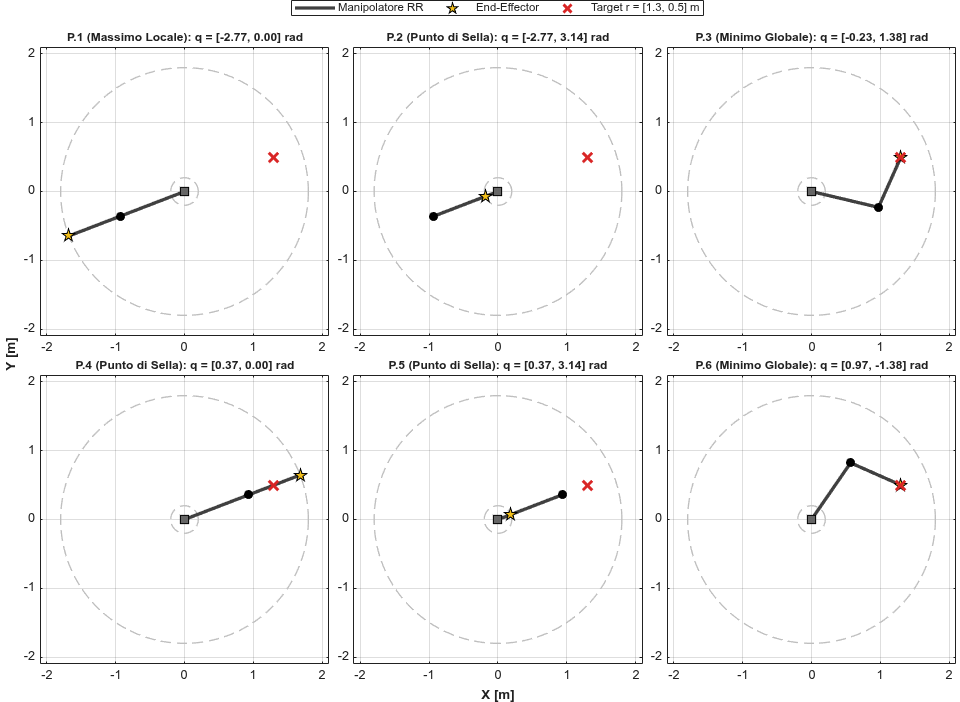

% --- Figura 1: Visualizzazione Vettoriale delle 6 Configurazioni Critiche ---
col_link  = [0.25, 0.25, 0.25];
col_red   = [0.85, 0.15, 0.15];
col_green = [0.15, 0.65, 0.20];
col_blue  = [0.15, 0.35, 0.85];

theta_ws = linspace(0, 2*pi, 200);
R_ws_max = l_val(1) + l_val(2);
R_ws_min = abs(l_val(1) - l_val(2));
e_q_sub  = subs(e_q, [l1, l2, rx, ry], [l_val(1), l_val(2), r_val(1), r_val(2)]);

figure('Name', 'Configurazioni Critiche del Manipolatore RR', 'Color', 'w', ...
    'Units', 'normalized', 'Position', [0.22, 0.14, 0.50, 0.65]);
t = tiledlayout(2, 3, 'TileSpacing', 'tight', 'Padding', 'tight');

for k = 1:size(puntiCritici, 1)
    nexttile;
    hold on; grid on; box on; axis equal;

    q1_c = puntiCritici(k, 1);
    q2_c = puntiCritici(k, 2);

    % Classificazione punto critico tramite autovalori di H_V e norma errore
    H_c   = double(subs(H_V_val, [q1, q2], [q1_c, q2_c]));
    lam   = eig(H_c);
    err_c = norm(double(subs(e_q_sub, [q1, q2], [q1_c, q2_c])));
    if all(lam > 0)
        if err_c < 1e-5
            tipo_str = 'Minimo Globale';
        else
            tipo_str = 'Minimo Locale';
        end
    elseif all(lam < 0)
        tipo_str = 'Massimo Locale';
    else
        tipo_str = 'Punto di Sella';
    end

    % Bordi spazio di lavoro (tratteggio leggero)
    plot(R_ws_max*cos(theta_ws), R_ws_max*sin(theta_ws), '--', ...
        'Color', [0.75, 0.75, 0.75], 'LineWidth', 1.0, 'HandleVisibility', 'off');
    plot(R_ws_min*cos(theta_ws), R_ws_min*sin(theta_ws), '--', ...
        'Color', [0.75, 0.75, 0.75], 'LineWidth', 1.0, 'HandleVisibility', 'off');

    % Cinematica diretta della configurazione critica k
    p0 = [0, 0];
    p1 = [l_val(1)*cos(q1_c), l_val(1)*sin(q1_c)];
    p2 = p1 + [l_val(2)*cos(q1_c + q2_c), l_val(2)*sin(q1_c + q2_c)];
    pts_rr = [p0; p1; p2];

    % Disegno bracci, base, giunto intermedio, End-Effector e Target r
    h_arm = plot(pts_rr(:,1), pts_rr(:,2), '-', 'Color', col_link, 'LineWidth', 2.5);
    plot(p0(1), p0(2), 's', 'MarkerSize', 8, ...
        'MarkerFaceColor', [0.4, 0.4, 0.4], 'MarkerEdgeColor', 'k');
    plot(p1(1), p1(2), 'o', 'MarkerSize', 6, ...
        'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
    h_ee = plot(p2(1), p2(2), 'p', 'MarkerSize', 10, ...
        'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k');
    h_tgt = plot(r_val(1), r_val(2), 'x', 'MarkerSize', 10, ...
        'Color', col_red, 'LineWidth', 2.2);

    title(sprintf('P.%d (%s): q = [%.2f, %.2f] rad', k, tipo_str, q1_c, q2_c), ...
        'FontSize', 9, 'FontWeight', 'bold');
    xlim([-2.1, 2.1]); ylim([-2.1, 2.1]);
    xticks(-2:1:2); yticks(-2:1:2);

    if k == 1
        lgd1 = legend([h_arm, h_ee, h_tgt], ...
            {'Manipolatore RR', 'End-Effector', 'Target r = [1.3, 0.5] m'}, ...
            'Orientation', 'horizontal');
        lgd1.Layout.Tile = 'north';
    end
    hold off;
end
xlabel(t, 'X [m]', 'FontSize', 10, 'FontWeight', 'bold');
ylabel(t, 'Y [m]', 'FontSize', 10, 'FontWeight', 'bold');

Per comprendere visivamente il comportamento degli algoritmi di ottimizzazione, è essenziale visualizzare la funzione di costo $V(q)$. Questo viene fatto generando una mappa di curve di livello 2D della funzione di costo nello spazio dei giunti $(q_1 ,q_2 )$. Su questo grafico, verranno sovrapposti i punti critici calcolati e classificati. Questo permette di vedere dove si trovano i minimi, i massimi e i punti di sella, che possono deviare o intrappolare gli algoritmi.

l_val = [1, 0.8];
for i = 1:size(puntiCritici, 1)
    q1Crit = puntiCritici(i,1);
    q2Crit = puntiCritici(i,2);
    l1Crit = l_val(1);
    l2Crit = l_val(2);
    fprintf('Configurazione Critica (q1, q2) = (%.4f, %.4f)\n', q1Crit, q2Crit);

    % Posizione Base Giunto
    x0 = 0;
    y0 = 0;

    % Calcolo Coordinate Fine Primo Braccio (x1, y1)
    x1Crit = double(l1Crit * cos(q1Crit));
    y1Crit = double(l1Crit * sin(q1Crit));

    % Calcolo Coordinate End Effector (x2, y2) Rispetto Al Sistema Di Riferimento Base
    x2Crit = double(x1Crit + l2Crit * cos(q1Crit + q2Crit));
    y2Crit = double(y1Crit + l2Crit * sin(q1Crit + q2Crit));

    fprintf('\t Posizione Giunto 0 (Base) (x0, y0) = (%.4f, %.4f)\n', x0, y0);
    fprintf('\t Posizione Giunto 1        (x1, y1) = (%.4f, %.4f)\n', x1Crit, y1Crit);
    fprintf('\t Posizione Giunto 2 (EE)   (x2, y2) = (%.4f, %.4f)\n', x2Crit, y2Crit);

end

Configurazione Critica (q1, q2) = (-2.7744, 0.0000)


	 Posizione Giunto 0 (Base) (x0, y0) = (0.0000, 0.0000)


	 Posizione Giunto 1        (x1, y1) = (-0.9333, -0.3590)


	 Posizione Giunto 2 (EE)   (x2, y2) = (-1.6800, -0.6462)


Configurazione Critica (q1, q2) = (-2.7744, 3.1416)


	 Posizione Giunto 0 (Base) (x0, y0) = (0.0000, 0.0000)


	 Posizione Giunto 1        (x1, y1) = (-0.9333, -0.3590)


	 Posizione Giunto 2 (EE)   (x2, y2) = (-0.1867, -0.0718)


Configurazione Critica (q1, q2) = (-0.2323, 1.3822)


	 Posizione Giunto 0 (Base) (x0, y0) = (0.0000, 0.0000)


	 Posizione Giunto 1        (x1, y1) = (0.9731, -0.2302)


	 Posizione Giunto 2 (EE)   (x2, y2) = (1.3000, 0.5000)


Configurazione Critica (q1, q2) = (0.3672, 0.0000)


	 Posizione Giunto 0 (Base) (x0, y0) = (0.0000, 0.0000)


	 Posizione Giunto 1        (x1, y1) = (0.9333, 0.3590)


	 Posizione Giunto 2 (EE)   (x2, y2) = (1.6800, 0.6462)


Configurazione Critica (q1, q2) = (0.3672, 3.1416)


	 Posizione Giunto 0 (Base) (x0, y0) = (0.0000, 0.0000)


	 Posizione Giunto 1        (x1, y1) = (0.9333, 0.3590)


	 Posizione Giunto 2 (EE)   (x2, y2) = (0.1867, 0.0718)


Configurazione Critica (q1, q2) = (0.9666, -1.3822)


	 Posizione Giunto 0 (Base) (x0, y0) = (0.0000, 0.0000)


	 Posizione Giunto 1        (x1, y1) = (0.5681, 0.8230)


	 Posizione Giunto 2 (EE)   (x2, y2) = (1.3000, 0.5000)


## Mappa Di Livello Della Funzione Di Costo E Punti Critici

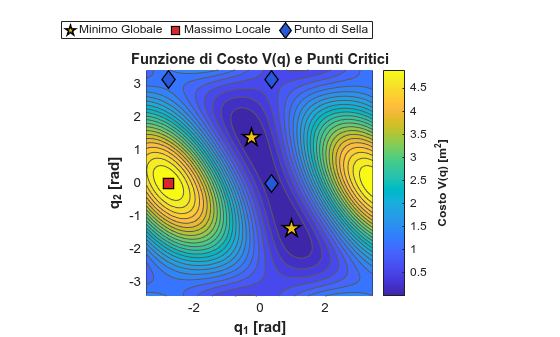

col_red   = [0.85, 0.15, 0.15];
col_green = [0.15, 0.65, 0.20];
col_blue  = [0.15, 0.35, 0.85];

% Definizione Dominio (con margine per includere interamente i punti su ±pi) e Calcolo V(q)
q1_range = linspace(-pi - 0.30, pi + 0.30, 200);
q2_range = linspace(-pi - 0.30, pi + 0.30, 200);
[Q1, Q2] = meshgrid(q1_range, q2_range);

V_fun  = matlabFunction(V_val, 'Vars', {q1, q2});
V_grid = double(V_fun(Q1, Q2));

figure('Name', 'Funzione di Costo V(q) e Punti Critici', 'Color', 'w');
hold on; grid on; box on; axis equal; axis tight;
contourf(Q1, Q2, V_grid, 25, 'LineColor', [0.35, 0.35, 0.35], 'LineWidth', 0.4);
colormap(gca, 'parula');
cb = colorbar;
cb.Label.String = 'Costo V(q) [m^2]';
cb.Label.FontWeight = 'bold';

xlabel('q_1 [rad]', 'FontWeight', 'bold');
ylabel('q_2 [rad]', 'FontWeight', 'bold');
title('Funzione di Costo V(q) e Punti Critici', 'FontSize', 11, 'FontWeight', 'bold');

% Sovrapposizione Punti Critici Classificati
e_q_val = subs(e_q, [l1, l2, rx, ry], [l_val(1), l_val(2), r_val(1), r_val(2)]);

for i = 1:size(puntiCritici, 1)
    qCrit = puntiCritici(i, :);
    H_V_Current = double(subs(H_V_val, [q1, q2], qCrit));
    lambda = eig(H_V_Current);
    e_current_norm = norm(double(subs(e_q_val, [q1, q2], qCrit)));

    if all(lambda > 0)
        if e_current_norm < 1e-5
            plot(qCrit(1), qCrit(2), 'p', 'MarkerSize', 14, ...
                'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
        else
            plot(qCrit(1), qCrit(2), 'o', 'MarkerSize', 10, ...
                'MarkerFaceColor', col_green, 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
        end
    elseif all(lambda < 0)
        plot(qCrit(1), qCrit(2), 's', 'MarkerSize', 10, ...
            'MarkerFaceColor', col_red, 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
    else
        plot(qCrit(1), qCrit(2), 'd', 'MarkerSize', 9, ...
            'MarkerFaceColor', col_blue, 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
    end
end

% Proxy Handles per Legenda Esterna Orizzontale
h_min_g = plot(NaN, NaN, 'p', 'MarkerSize', 13, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
h_max_l = plot(NaN, NaN, 's', 'MarkerSize', 10, ...
    'MarkerFaceColor', col_red, 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
h_sella = plot(NaN, NaN, 'd', 'MarkerSize', 9, ...
    'MarkerFaceColor', col_blue, 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);

legend([h_min_g, h_max_l, h_sella], ...
    {'Minimo Globale', 'Massimo Locale', 'Punto di Sella'}, ...
    'Location', 'northoutside', 'Orientation', 'horizontal');
hold off;

## Simulazione Numerica Iterativa Dell'Algoritmo Di Newton

Per le simulazioni iterative di Newton e del Gradiente si considerano nuovi parametri geometrici e di task: lunghezze dei bracci $l_1 = l_2 = 1.0$ e posa desiderata $r = [1.0, 1.0]^T$.

fprintf('----- Algoritmo Di Newton Iterativo -----');

----- Algoritmo Di Newton Iterativo -----

% Lunghezze Bracci
l1_val = 1.0;
l2_val = 1.0;

% Posa Desiderata
r_val = [1.0; 1.0];

% Parametri Robot
T = 0.1;
k_gain = 5;
K_num = k_gain * eye(2);

% Creazione Funzioni Simboliche
fr_fun = matlabFunction(fr_q, 'Vars', {l1, l2, q1, q2});
J_fun = matlabFunction(J_q, 'Vars', {l1, l2, q1, q2});

% Configurazioni Iniziali (q_0^(1), q_0^(2), q_0^(3))
q_initial_conditions = [
    pi/4, pi/4;      % Configurazione iniziale q_{0,1}
    0, pi/2;         % Configurazione iniziale q_{0,2}
    -pi/3, pi/6      % Configurazione iniziale q_{0,3}
];

nrSol = size(q_initial_conditions, 1);
all_q_newton = cell(nrSol, 1);
all_err_newton = cell(nrSol, 1);

for i = 1:nrSol
    q_k = q_initial_conditions(i, :).'; % Vettore Colonna

    fprintf('Configurazione iniziale q_{0,%d} = [%.4f, %.4f]\n', i, q_k(1), q_k(2));

    % Inizializzazione Array Cronologia
    q_history = zeros(2, 100 + 1);
    error_history = zeros(1, 100 + 1);
    q_history(:, 1) = q_k;
    num_steps = 0;
    num_err = 0;

    for k = 1:100
        pos_k = fr_fun(l1_val, l2_val, q_k(1), q_k(2));

        e_k = r_val - pos_k;
        error_norm = norm(e_k);
        num_err = k;
        error_history(k) = error_norm;

        if error_norm < 1e-6
            if num_steps == 1
                fprintf('\t Convergenza Raggiunta In 1 Iterazione.\n');
            else
                fprintf('\t Convergenza Raggiunta In %d Iterazioni.\n', num_steps);
            end
            break;
        end

        J_k = J_fun(l1_val, l2_val, q_k(1), q_k(2));

        if abs(det(J_k)) < 1e-5
            fprintf('\t Attenzione: Jacobiano Quasi Singolare (det(J) = %.2e). Interruzione.\n', det(J_k));
            break;
        end

        % f. Aggiornamento Configurazione Giunti (Formula di Newton)
        % q_{k+1} = q_k + T * J^{-1}(q_k) * K * [r - f_r(q_k)]
        q_k = q_k + T * (J_k \ (K_num * e_k));

        % Salvataggio Nuova Configurazione
        num_steps = num_steps + 1;
        q_history(:, num_steps + 1) = q_k;
    end

    if num_steps == 100 && error_norm >= 1e-6
        fprintf('\t Algoritmo Terminato Per Numero Massimo Iterazioni.\n');
    end

    % Tronca Cronologia Al Numero Di Stati Effettivi (iniziale + passi eseguiti)
    q_history = q_history(:, 1:num_steps + 1);
    all_q_newton{i} = q_history;
    all_err_newton{i} = error_history(1:num_err);

    % Visualizzazione Risultati
    q_finale = q_history(:, end);
    pos_finale = fr_fun(l1_val, l2_val, q_finale(1), q_finale(2));

    fprintf('\t Configurazione finale q_f: [%.4f, %.4f]\n', q_finale(1), q_finale(2));
    fprintf('\t Posizione finale EE [x; y]: [%.4f; %.4f]\n', pos_finale(1), pos_finale(2));
    fprintf('\t Errore finale (norma): %.2e\n', norm(r_val - pos_finale));
end

Configurazione iniziale q_{0,1} = [0.7854, 0.7854]


	 Convergenza Raggiunta In 20 Iterazioni.


	 Configurazione finale q_f: [0.0000, 1.5708]


	 Posizione finale EE [x; y]: [1.0000; 1.0000]


	 Errore finale (norma): 6.98e-07


Configurazione iniziale q_{0,2} = [0.0000, 1.5708]


	 Convergenza Raggiunta In 0 Iterazioni.


	 Configurazione finale q_f: [0.0000, 1.5708]


	 Posizione finale EE [x; y]: [1.0000; 1.0000]


	 Errore finale (norma): 0.00e+00


Configurazione iniziale q_{0,3} = [-1.0472, 0.5236]


	 Convergenza Raggiunta In 26 Iterazioni.


	 Configurazione finale q_f: [-4.7124, 4.7124]


	 Posizione finale EE [x; y]: [1.0000; 1.0000]


	 Errore finale (norma): 6.88e-07


## Simulazione Numerica Iterativa Dell'Algoritmo Del Gradiente

fprintf('----- Algoritmo Gradiente Iterativo -----');

----- Algoritmo Gradiente Iterativo -----

% Guadagno scalare continuo e learning rate discreto alpha' = T * alpha
alpha_val = 0.8;
alpha_prime = T * alpha_val;
all_q_grad = cell(nrSol, 1);
all_err_grad = cell(nrSol, 1);

for i = 1:nrSol
    q_k = q_initial_conditions(i, :).'; % Vettore Colonna

    fprintf('\nConfigurazione iniziale q_{0,%d} = [%.4f, %.4f]\n', i, q_k(1), q_k(2));

    % Inizializzazione Array Cronologia
    q_history_grad = zeros(2, 500 + 1);
    error_history_grad = zeros(1, 500 + 1);
    q_history_grad(:, 1) = q_k;

    num_steps = 0;
    num_err = 0;

    for k = 1:500
        % Calcolo Posizione Corrente EE
        pos_k = fr_fun(l1_val, l2_val, q_k(1), q_k(2));

        % Calcolo Errore Corrente
        e_k = r_val - pos_k;
        error_norm = norm(e_k);
        num_err = k;
        error_history_grad(k) = error_norm;

        % Condizione di Arresto per Convergenza
        if error_norm < 1e-6
            if num_steps == 1
                fprintf('\t Convergenza Raggiunta In 1 Iterazione.\n');
            else
                fprintf('\t Convergenza Raggiunta In %d Iterazioni.\n', num_steps);
            end
            break;
        end

        % Calcolo Jacobiano alla Configurazione Corrente
        J_k = J_fun(l1_val, l2_val, q_k(1), q_k(2));

        % Robustezza alle Singolarità
        % La trasposta J_k.' esiste sempre, quindi l'algoritmo non fallisce numericamente ma
        % rallenta la convergenza fino a fermarsi se si trova esattamente su un minimo locale.

        % Aggiornamento Configurazione Giunti (Formula del Gradiente con alpha' = T * alpha)
        % q_{k+1} = q_k + alpha' * J(q_k)^T * [r - f_r(q_k)]
        q_k = q_k + alpha_prime * J_k.' * e_k;

        % Salvataggio Nuova Configurazione
        num_steps = num_steps + 1;
        q_history_grad(:, num_steps + 1) = q_k;
    end

    if num_steps == 500 && error_norm >= 1e-6
        fprintf('\t Algoritmo Terminato Per Numero Massimo Iterazioni.\n');
    end
    % Tronca Cronologia Al Numero Di Stati Effettivi (iniziale + passi eseguiti)
    q_history_grad = q_history_grad(:, 1:num_steps + 1);
    all_q_grad{i} = q_history_grad;
    all_err_grad{i} = error_history_grad(1:num_err);

    % Visualizzazione Risultati
    q_finale_grad = q_history_grad(:, end);
    pos_finale_grad = fr_fun(l1_val, l2_val, q_finale_grad(1), q_finale_grad(2));

    fprintf('\t Configurazione Finale q_f: [%.4f, %.4f]\n', q_finale_grad(1), q_finale_grad(2));
    fprintf('\t Posizione Finale EE [x; y]: [%.4f; %.4f]\n', pos_finale_grad(1), pos_finale_grad(2));
    fprintf('\t Errore Finale (norma): %.2e\n', norm(r_val - pos_finale_grad));
end


Configurazione iniziale q_{0,1} = [0.7854, 0.7854]


	 Convergenza Raggiunta In 467 Iterazioni.


	 Configurazione Finale q_f: [0.0000, 1.5708]


	 Posizione Finale EE [x; y]: [1.0000; 1.0000]


	 Errore Finale (norma): 9.75e-07



Configurazione iniziale q_{0,2} = [0.0000, 1.5708]


	 Convergenza Raggiunta In 0 Iterazioni.


	 Configurazione Finale q_f: [0.0000, 1.5708]


	 Posizione Finale EE [x; y]: [1.0000; 1.0000]


	 Errore Finale (norma): 0.00e+00



Configurazione iniziale q_{0,3} = [-1.0472, 0.5236]


	 Convergenza Raggiunta In 402 Iterazioni.


	 Configurazione Finale q_f: [0.0000, 1.5708]


	 Posizione Finale EE [x; y]: [1.0000; 1.0000]


	 Errore Finale (norma): 9.91e-07


## Confronto Traiettorie E Velocità Di Convergenza: Newton Contro Gradiente

col_red   = [0.85, 0.15, 0.15];
col_green = [0.15, 0.65, 0.20];
col_blue  = [0.15, 0.35, 0.85];
colors_q  = [col_red; col_green; col_blue];

% Mappa colori attenuata (parula pastello) e funzione di costo numerica
cmap_soft   = 0.55 * parula(256) + 0.45 * ones(256, 3);
V_clim_max  = 6.0;
base_minima = [0, pi/2; pi/2, -pi/2];
V_iter_sym  = subs(V, [l1, l2, rx, ry], [l1_val, l2_val, r_val(1), r_val(2)]);
V_iter_fun  = matlabFunction(V_iter_sym, 'Vars', {q1, q2});

### Grafici Algoritmo Di Newton

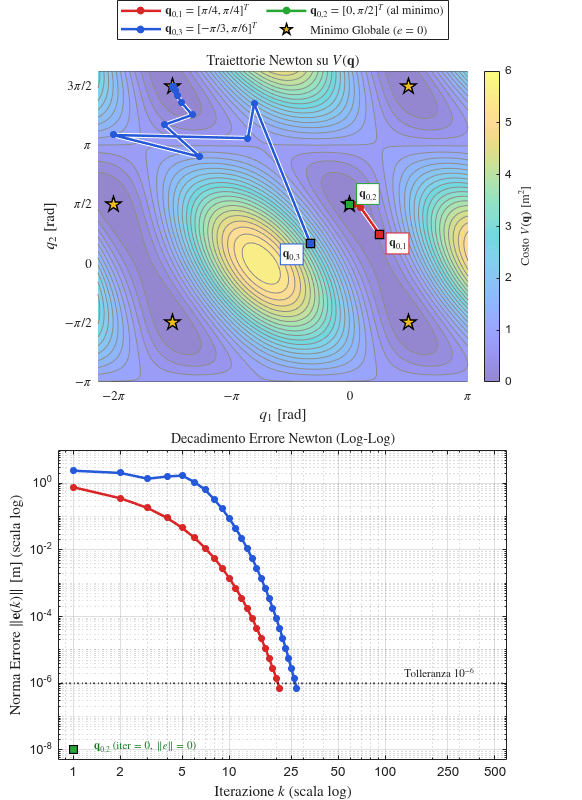

all_newt_pts = cell2mat(all_q_newton.');
dx_n = [min(-pi, min(all_newt_pts(1,:)) - 0.4), max(pi, max(all_newt_pts(1,:)) + 0.4)];
dy_n = [min(-pi, min(all_newt_pts(2,:)) - 0.4), max(pi, max(all_newt_pts(2,:)) + 0.4)];
[Q1_n, Q2_n] = meshgrid(linspace(dx_n(1), dx_n(2), 180), linspace(dy_n(1), dy_n(2), 180));
V_grid_n = double(V_iter_fun(Q1_n, Q2_n));

figure('Name', 'Algoritmo di Newton: Traiettorie e Convergenza', 'Color', 'w', ...
    'Units', 'normalized', 'Position', [0.30, 0.04, 0.36, 0.88]);
t_n = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'tight');

% --- Newton 1: Traiettorie su V(q) ---
ax_n1 = nexttile;
hold on; grid on; box on; axis equal;
contourf(Q1_n, Q2_n, V_grid_n, 22, 'LineColor', [0.55, 0.55, 0.55], 'LineWidth', 0.35);
colormap(gca, cmap_soft);
clim([0, V_clim_max]);
cb_n = colorbar;
cb_n.Label.String = 'Costo $V(\mathbf{q})\;[\mathrm{m}^2]$';
cb_n.Label.Interpreter = 'latex';
cb_n.Label.FontWeight = 'bold';

for bm = 1:size(base_minima, 1)
    for k1 = -2:2
        for k2 = -2:2
            qm = base_minima(bm,:) + 2*pi*[k1, k2];
            if qm(1) >= dx_n(1) && qm(1) <= dx_n(2) && qm(2) >= dy_n(1) && qm(2) <= dy_n(2)
                plot(qm(1), qm(2), 'p', 'MarkerSize', 12, ...
                    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', ...
                    'LineWidth', 1.1, 'HandleVisibility', 'off');
            end
        end
    end
end

off_n   = [0.22, -0.25; 0.22, 0.28; -0.24, -0.28];
align_n = {'left', 'left', 'right'};
for i = 1:nrSol
    q_tr = all_q_newton{i};
    if size(q_tr, 2) > 1
        plot(q_tr(1,:), q_tr(2,:), '-', 'Color', [1, 1, 1], 'LineWidth', 3.4, 'HandleVisibility', 'off');
        plot(q_tr(1,:), q_tr(2,:), '-o', 'Color', colors_q(i,:), ...
            'LineWidth', 1.9, 'MarkerSize', 3.5, 'MarkerFaceColor', colors_q(i,:));
    end
    q0_i = q_initial_conditions(i, :);
    plot(q0_i(1), q0_i(2), 's', 'MarkerSize', 8, ...
        'MarkerFaceColor', colors_q(i,:), 'MarkerEdgeColor', 'k', 'LineWidth', 1.3);
    text(q0_i(1) + off_n(i,1), q0_i(2) + off_n(i,2), sprintf('$\\mathbf{q}_{0,%d}$', i), ...
        'Interpreter', 'latex', 'FontSize', 9, 'FontWeight', 'bold', ...
        'HorizontalAlignment', align_n{i}, 'BackgroundColor', [1, 1, 1], ...
        'EdgeColor', colors_q(i,:), 'Margin', 1.2);
end

xlim(dx_n); ylim(dy_n);
xticks([-2*pi, -pi, 0, pi]);
xticklabels({'$-2\pi$', '$-\pi$', '$0$', '$\pi$'});
yticks([-pi, -pi/2, 0, pi/2, pi, 3*pi/2]);
yticklabels({'$-\pi$', '$-\pi/2$', '$0$', '$\pi/2$', '$\pi$', '$3\pi/2$'});
set(gca, 'TickLabelInterpreter', 'latex');
xlabel('$q_1\;[\mathrm{rad}]$', 'Interpreter', 'latex', 'FontWeight', 'bold');
ylabel('$q_2\;[\mathrm{rad}]$', 'Interpreter', 'latex', 'FontWeight', 'bold');
title('Traiettorie Newton su $V(\mathbf{q})$', 'Interpreter', 'latex', 'FontSize', 10.5, 'FontWeight', 'bold');
hold off;

% --- Newton 2: Decadimento Errore (Log-Log) ---
nexttile;
hold on; grid on; box on;
set(gca, 'XScale', 'log', 'YScale', 'log');
yline(1e-6, ':k', 'LineWidth', 1.2, 'HandleVisibility', 'off');
text(220, 2.2e-6, 'Tolleranza $10^{-6}$', 'Interpreter', 'latex', ...
    'FontSize', 8.5, 'HorizontalAlignment', 'center');

for i = 1:nrSol
    if i == 2
        plot(1, 1e-8, 's', 'MarkerSize', 7.5, ...
            'MarkerFaceColor', colors_q(i,:), 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
        text(1.35, 1.3e-8, '$\mathbf{q}_{0,2}$ ($\mathrm{iter}=0,\;\|e\|=0$)', ...
            'Interpreter', 'latex', 'FontSize', 8.5, 'Color', colors_q(i,:) * 0.75);
    else
        e_vec = max(all_err_newton{i}, 1e-8);
        loglog(1:length(e_vec), e_vec, '-o', 'Color', colors_q(i,:), ...
            'LineWidth', 1.9, 'MarkerSize', 3.5, 'MarkerFaceColor', colors_q(i,:));
    end
end

xlim([0.8, 600]); ylim([5e-9, 10]);
xticks([1, 2, 5, 10, 25, 50, 100, 250, 500]);
xticklabels({'1', '2', '5', '10', '25', '50', '100', '250', '500'});
yticks(10.^(-8:2:0));
xlabel('Iterazione $k$ (scala log)', 'Interpreter', 'latex', 'FontWeight', 'bold');
ylabel('Norma Errore $\|\mathbf{e}(k)\|\;[\mathrm{m}]$ (scala log)', 'Interpreter', 'latex', 'FontWeight', 'bold');
title('Decadimento Errore Newton (Log-Log)', 'Interpreter', 'latex', 'FontSize', 10.5, 'FontWeight', 'bold');
hold off;

% Legenda condivisa Newton in alto
hold(ax_n1, 'on');
h_leg_n = gobjects(1, 4);
for i = 1:nrSol
    h_leg_n(i) = plot(ax_n1, NaN, NaN, '-o', 'Color', colors_q(i,:), ...
        'MarkerFaceColor', colors_q(i,:), 'LineWidth', 1.9, 'MarkerSize', 4);
end
h_leg_n(4) = plot(ax_n1, NaN, NaN, 'p', 'MarkerSize', 11, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'LineWidth', 1.1);
hold(ax_n1, 'off');

lgd_n = legend(ax_n1, h_leg_n, ...
    {'$\mathbf{q}_{0,1} = [\pi/4,\, \pi/4]^T$', ...
     '$\mathbf{q}_{0,2} = [0,\, \pi/2]^T$ (al minimo)', ...
     '$\mathbf{q}_{0,3} = [-\pi/3,\, \pi/6]^T$', ...
     'Minimo Globale ($e = 0$)'}, ...
    'Interpreter', 'latex', 'Orientation', 'horizontal', 'NumColumns', 2, 'FontSize', 8.8);
lgd_n.Layout.Tile = 'north';

### Grafici Algoritmo Del Gradiente

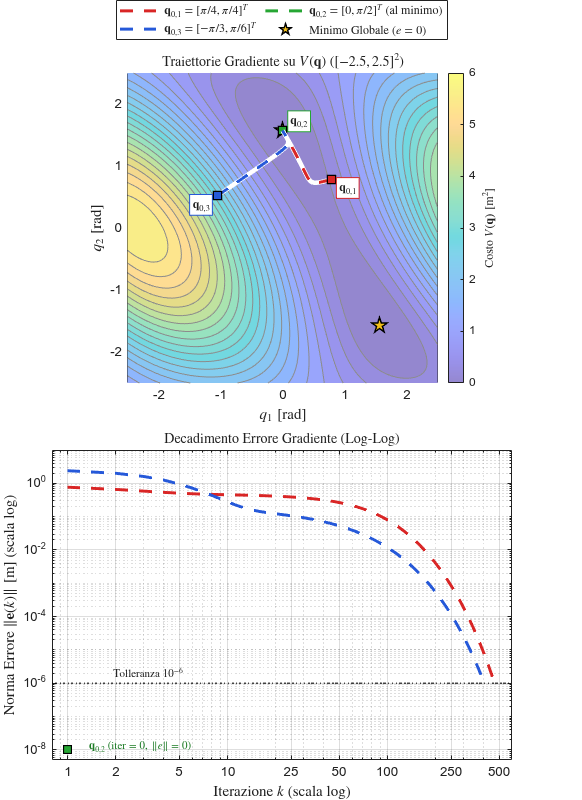

dx_g = [-2.5, 2.5];
dy_g = [-2.5, 2.5];
[Q1_g, Q2_g] = meshgrid(linspace(dx_g(1), dx_g(2), 180), linspace(dy_g(1), dy_g(2), 180));
V_grid_g = double(V_iter_fun(Q1_g, Q2_g));

figure('Name', 'Algoritmo del Gradiente: Traiettorie e Convergenza', 'Color', 'w', ...
    'Units', 'normalized', 'Position', [0.30, 0.04, 0.36, 0.88]);
t_g = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'tight');

% --- Gradiente 1: Traiettorie su V(q) (Zoom [-2.5, 2.5]^2) ---
ax_g1 = nexttile;
hold on; grid on; box on; axis equal;
contourf(Q1_g, Q2_g, V_grid_g, 22, 'LineColor', [0.55, 0.55, 0.55], 'LineWidth', 0.35);
colormap(gca, cmap_soft);
clim([0, V_clim_max]);
cb_g = colorbar;
cb_g.Label.String = 'Costo $V(\mathbf{q})\;[\mathrm{m}^2]$';
cb_g.Label.Interpreter = 'latex';
cb_g.Label.FontWeight = 'bold';

for bm = 1:size(base_minima, 1)
    qm = base_minima(bm, :);
    if qm(1) >= dx_g(1) && qm(1) <= dx_g(2) && qm(2) >= dy_g(1) && qm(2) <= dy_g(2)
        plot(qm(1), qm(2), 'p', 'MarkerSize', 12, ...
            'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.1, 'HandleVisibility', 'off');
    end
end

off_g   = [0.11, -0.14; 0.11, 0.15; -0.11, -0.15];
align_g = {'left', 'left', 'right'};
for i = 1:nrSol
    q_tr = all_q_grad{i};
    if size(q_tr, 2) > 1
        plot(q_tr(1,:), q_tr(2,:), '-', 'Color', [1, 1, 1], 'LineWidth', 3.4, 'HandleVisibility', 'off');
        plot(q_tr(1,:), q_tr(2,:), '--', 'Color', colors_q(i,:), 'LineWidth', 2.2);
    end
    q0_i = q_initial_conditions(i, :);
    plot(q0_i(1), q0_i(2), 's', 'MarkerSize', 8, ...
        'MarkerFaceColor', colors_q(i,:), 'MarkerEdgeColor', 'k', 'LineWidth', 1.3);
    text(q0_i(1) + off_g(i,1), q0_i(2) + off_g(i,2), sprintf('$\\mathbf{q}_{0,%d}$', i), ...
        'Interpreter', 'latex', 'FontSize', 9, 'FontWeight', 'bold', ...
        'HorizontalAlignment', align_g{i}, 'BackgroundColor', [1, 1, 1], ...
        'EdgeColor', colors_q(i,:), 'Margin', 1.2);
end

xlim(dx_g); ylim(dy_g);
xticks([-2, -1, 0, 1, 2]);
yticks([-2, -1, 0, 1, 2]);
xlabel('$q_1\;[\mathrm{rad}]$', 'Interpreter', 'latex', 'FontWeight', 'bold');
ylabel('$q_2\;[\mathrm{rad}]$', 'Interpreter', 'latex', 'FontWeight', 'bold');
title('Traiettorie Gradiente su $V(\mathbf{q})$ ($[-2.5, 2.5]^2$)', 'Interpreter', 'latex', 'FontSize', 10.5, 'FontWeight', 'bold');
hold off;

% --- Gradiente 2: Decadimento Errore (Log-Log) ---
nexttile;
hold on; grid on; box on;
set(gca, 'XScale', 'log', 'YScale', 'log');
yline(1e-6, ':k', 'LineWidth', 1.2, 'HandleVisibility', 'off');
text(3.2, 2.2e-6, 'Tolleranza $10^{-6}$', 'Interpreter', 'latex', ...
    'FontSize', 8.5, 'HorizontalAlignment', 'center');

for i = 1:nrSol
    if i == 2
        plot(1, 1e-8, 's', 'MarkerSize', 7.5, ...
            'MarkerFaceColor', colors_q(i,:), 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
        text(1.35, 1.3e-8, '$\mathbf{q}_{0,2}$ ($\mathrm{iter}=0,\;\|e\|=0$)', ...
            'Interpreter', 'latex', 'FontSize', 8.5, 'Color', colors_q(i,:) * 0.75);
    else
        e_vec = max(all_err_grad{i}, 1e-8);
        loglog(1:length(e_vec), e_vec, '--', 'Color', colors_q(i,:), 'LineWidth', 2.2);
    end
end

xlim([0.8, 600]); ylim([5e-9, 10]);
xticks([1, 2, 5, 10, 25, 50, 100, 250, 500]);
xticklabels({'1', '2', '5', '10', '25', '50', '100', '250', '500'});
yticks(10.^(-8:2:0));
xlabel('Iterazione $k$ (scala log)', 'Interpreter', 'latex', 'FontWeight', 'bold');
ylabel('Norma Errore $\|\mathbf{e}(k)\|\;[\mathrm{m}]$ (scala log)', 'Interpreter', 'latex', 'FontWeight', 'bold');
title('Decadimento Errore Gradiente (Log-Log)', 'Interpreter', 'latex', 'FontSize', 10.5, 'FontWeight', 'bold');
hold off;

% Legenda condivisa Gradiente in alto
hold(ax_g1, 'on');
h_leg_g = gobjects(1, 4);
for i = 1:nrSol
    h_leg_g(i) = plot(ax_g1, NaN, NaN, '--', 'Color', colors_q(i,:), 'LineWidth', 2.2);
end
h_leg_g(4) = plot(ax_g1, NaN, NaN, 'p', 'MarkerSize', 11, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'LineWidth', 1.1);
hold(ax_g1, 'off');

lgd_g = legend(ax_g1, h_leg_g, ...
    {'$\mathbf{q}_{0,1} = [\pi/4,\, \pi/4]^T$', ...
     '$\mathbf{q}_{0,2} = [0,\, \pi/2]^T$ (al minimo)', ...
     '$\mathbf{q}_{0,3} = [-\pi/3,\, \pi/6]^T$', ...
     'Minimo Globale ($e = 0$)'}, ...
    'Interpreter', 'latex', 'Orientation', 'horizontal', 'NumColumns', 2, 'FontSize', 8.8);
lgd_g.Layout.Tile = 'north';

### Considerazioni Sul Confronto Tra Newton E Gradiente

Dai risultati delle simulazioni emergono due differenze principali tra i due metodi:

- **Velocità di convergenza**: L'algoritmo di Newton converge molto più rapidamente (in circa $20\text{--}26$ iterazioni di aggiornamento) rispetto all'algoritmo del Gradiente (che richiede circa $402\text{--}467$ iterazioni a parità di tolleranza $10^{-6}$). Da $\mathbf{q}_{0,2}=[0,\pi/2]^T$, essendo già sulla soluzione esatta, entrambi terminano immediatamente con $0$ iterazioni.

- **Comportamento vicino alle singolarità e scelta del ramo**: Partendo da $\mathbf{q}_{0,3}=[-\pi/3,\pi/6]^T$, l'algoritmo di Newton transita in prossimità della singolarità $q_2=\pi$ (dove $J^{-1}$ amplifica il passo) e converge al ramo alternativo $[-4.7124,\; 4.7124]\;\mathrm{rad}$ (equivalente modulo $2\pi$ a $[\pi/2,\;-\pi/2]^T$). L'algoritmo del Gradiente, invece, utilizzando $J^T$ non soffre di amplificazioni singolari e scende regolarmente verso il minimo più vicino $[0,\;\pi/2]^T$.